# Chapter 4. Numerical Differentiation and Integration

## 4.1 Numerical Differentiation

### Forward and Backward Differences

For small $h$,


$$f'(x) \approx \frac{f(x+h) - f(x_0)}{h}$$


$h > 0$: the forward-difference formula

$h <0$: the backward-difference formula

### Example 1

Use the forward-difference formula to approximate the derivative of $f(x) = \ln x$ at $x_0 = 1.8$ using $h = 0.1,\ h = 0.05$, and $h = 0.01$, and check the errors between the exact value $f'(1.8) = 5/9$.

f = @(x) log(x);
a = 1.8;
h_val = [0.1, 0.05, 0.01];
for h = h_val
    val = finite_difference(f,a,h);
    sprintf('the forward-difference: %.10f\t error: %.10f', val, abs(5/9 - val))
end

### Three-Point Midpoint Formula


$$f'(x_0) = \frac{1}{2h}\left[ -f(x_0-h) + f(x_0 + h)\right] - \frac{h^2}{6}f^{(3)}(\xi_1)$$


where $\xi_1$ lies between $x_0 - h$ and $x_0 + h$.

### Example

Use the three-point midpoint formula to approximate $f'(0.9)$, where $f(x) = \sin x$ with $h = 0.1,\ 0.05,\ 0.02,\ 0.01,\ 0.005,\ 0.002,\ 0.001$, and check the errors between the exact value $f'(0.9) = \cos 0.9$.

f = @(x) sin(x);
a = 0.9;
h_val = [0.1, 0.05, 0.02, 0.01, 0.005, 0.002, 0.001];
exact_val = cos(a);
for h = h_val
    val = three_point_mid(f,a,h);
    sprintf('Three-Point Midpoint: %.10f\t error: %.10f', val, abs(val - cos(0.9)))
end

### **5 decimal**

f = @(x) sin(x);
a = 0.9;
h_val = [0.1, 0.05, 0.02, 0.01, 0.005, 0.002, 0.001];
exact_val = cos(a);
for h = h_val
    val = three_point_mid_5decimal(f,a,h);
    sprintf('Three-Point Midpoint: %.5f\t error: %.10f', val, abs(val - cos(0.9)));
end

## 4.4 Composite Numerical Integration

### **Composite Simpson's Rule**

### **Theorem 4.4**

Let $f\in C^4[a, b]$, $n$ be even, $h = (b-a)/n$, and $x_j = a + j h$, for each $j = 0,\ 1,\ \cdots,\ n$. There exists a $\mu \in (a, b)$ for which the Composite Simpson's rule for $n$ subintervals can be written with its error term as


$$\int_a^b f(x)\ dx = \frac{h}{3}\left[f(x_0) +  2 \sum_{j=1}^{(n/2)-1} f(x_{2j}) + 4 \sum_{j=1}^{n/2} f(x_{2j-1}) + f(x_{n})\right] - \frac{(b - a)}{180}h^4 f^{(4)}(\mu).$$


### **Pseudo Code**

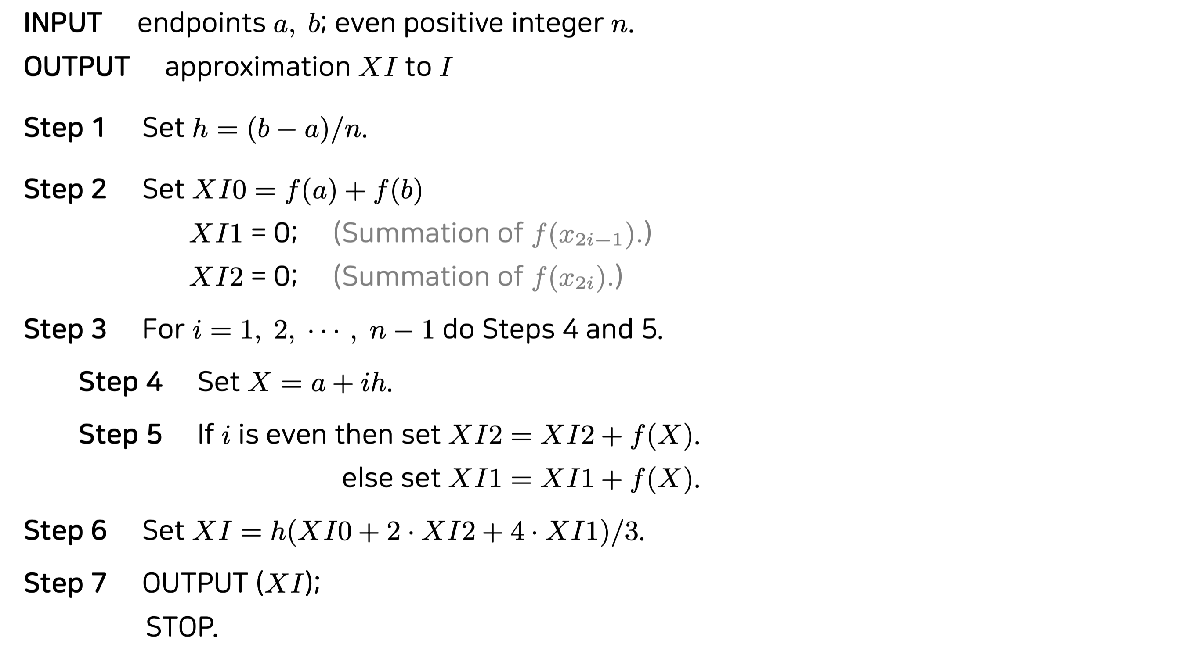

### Example

Approximate $\int_0^{\pi} \sin x\ dx$ with $n = 4,\ 8,\ 12,\ 16,$ and $20$.

f = @(x) sin(x);
nI = [4,8,12,16,20];
a = 0;
b = pi;
I = 2;
for n = nI
    XI = composite_simpson(f,a,b,n);
    sprintf("Composite Simpson's Rule: %.10f\t error: %.10f",XI, abs(XI - I))
end

### **Composite Trapezoidal Rule**

### **Theorem 4.5**

Let $f\in C^2[a, b]$, $h = (b-a)/n$, and $x_j = a + j h$, for each $j = 0,\ 1,\ \cdots,\ n$. There exists a $\mu \in (a, b)$ for which the Composite Trapezoidal rule for $n$ subintervals can be written with its error term as


$$\int_a^b f(x)\ dx = \frac{h}{2}\left[f(a) +  2 \sum_{j=1}^{n-1} f(x_{j}) + f(b)\right] - \frac{(b - a)}{12}h^2 f''(\mu).$$


### Example

Approximate $\int_0^{\pi} \sin x\ dx$ with $n = 4,\ 8,\ 12,\ 16,$ and $20$.

f = @(x) sin(x);
nI = [4,8,12,16,20];
a = 0;
b = pi;
I = 2;
for n = nI
    XI = composite_trapezoid(f,a,b,n);
    sprintf("Composite Trapezoidal Rule: %.10f\t error: %.10f",XI, abs(XI - I))
end

### **Composite Midpoint Rule**

### **Theorem 4.6**

Let $f\in C^2[a, b]$, $n$ be even, $h = (b-a)/(n+2)$, and $x_j = a + (j+1) h$, for each $j = -1,\ 0,\ \cdots,\ n+1$. There exists a $\mu \in (a, b)$ for which the Composite Midpoint rule for $n+2$ subintervals can be written with its error term as


$$\int_a^b f(x)\ dx = 2 h \sum_{j=0}^{n/2} f(x_{2j})+ \frac{(b - a)}{6}h^2 f''(\mu).$$


### Example

Approximate $\int_0^{\pi} \sin x\ dx$ with $n = 4,\ 8,\ 12,\ 16,$ and $20$.

f = @(x) sin(x);
nI = [4,8,12,16,20];
a = 0;
b = pi;
I = 2;
for n = nI
    XI = composite_midpoint(f,a,b,n);
    sprintf("Composite Midpoint Rule: %.10f\t error: %.10f",XI, abs(XI - I))
end

## 4.7 Gaussian Quadrature

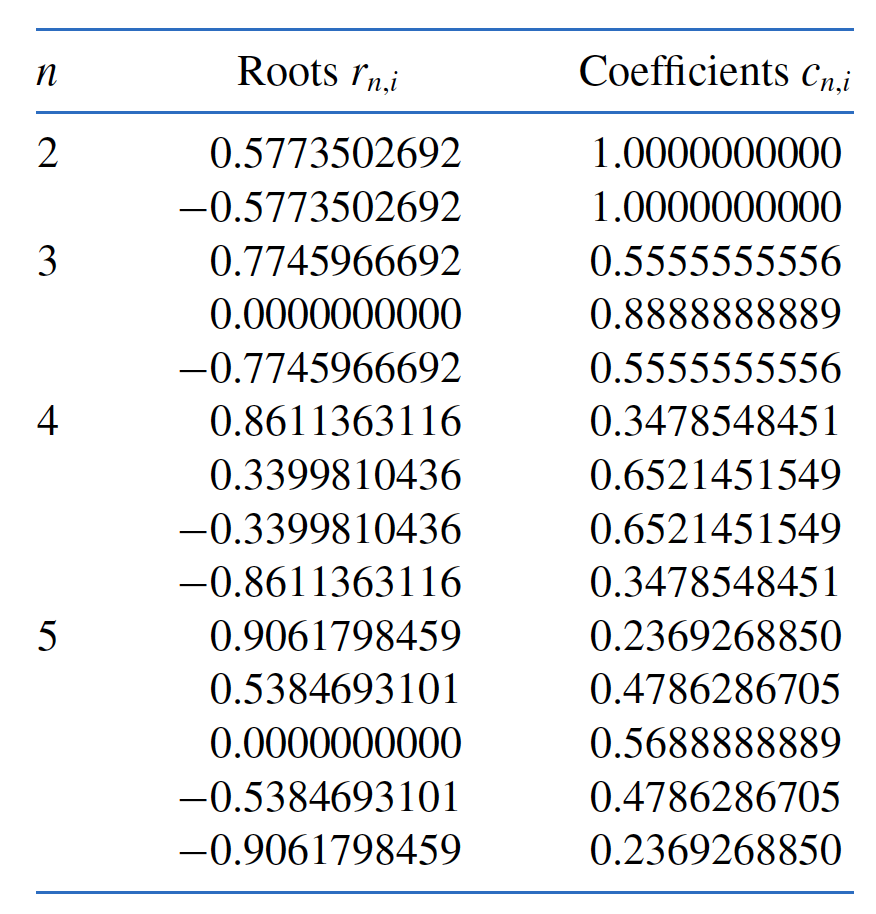

An integral $\int^b_a f(x)\ dx$ over an arbitrary $[a, b]$ can be transformed into an integral over $[-1, 1]$ by using the change of variables:


$$t = \frac{2x - a - b}{b - a} \quad \Longleftrightarrow \quad x = \frac{1}{2}[(b-a)t + a + b].$$


This permits Gaussian quadrature to be applied to any interval $[a, b]$, because


$$\int_a^b f(x)\ dx = \int_{-1}^1 f\left(\frac{(b-a)t + (b+a)}{2}\right) \frac{(b-a)}{2}\ dt.$$


### Example 2

Consider the integral $\int_1^3 x^6 - x^2\sin(2x)\ dx = 317.3442466.$

f = @(x) x^6 - x^2 * sin(2*x);
val = gaussian_quadrature(1,3,2,f);
disp(val)